addpath('../matlab_utils')
clear


1. Make a Matlab function that computes a Jacobian matrix in global frame given joint positions.

%function J = Jacobian(th1,th2,th3,th4,th5,th6)
%    syms theta
%    Rx = [1, 0, 0;
%        0, cos(theta), -sin(theta);
%        0 sin(theta), cos(theta);
%        ];
%    Ry = [cos(theta), 0, sin(theta);
%        0, 1, 0;
%        -sin(theta), 0, cos(theta);
%        ];
%    Rz = [cos(theta), -sin(theta), 0;
%        sin(theta), cos(theta), 0;
%        0 0, 1;
%        ];
%    syms p1 p2 p3
%    P = [p1;  p2; p3];
%    Tx =[Rx, P;
%        0 0 0 1];
%    Ty =[Ry, P;
%        0 0 0 1];
%    Tz =[Rz, P;
%        0 0 0 1];
%    T01 = subs(Tz,{theta,p1, p2, p3},{th1,0,0,0});
%    T12 = subs(Ty,{theta,p1, p2, p3},{th2,0,0,0.15});
%    T23 = subs(Ty,{theta,p1, p2, p3},{th3,0.3,0,0});
%    T34 = subs(Tx,{theta,p1, p2, p3},{th4,0.15,0,0});
%    T45 = subs(Ty,{theta,p1, p2, p3},{th5,0.1,0,0});
%    T56 = subs(Tx,{theta,p1, p2, p3},{th6,0.07,0,0});
%    T6EE = subs(Tx,{theta,p1, p2, p3},{0,0.05,0,0});
    
%    T5EE = Tmul(T56, T6EE);
%    T4EE = Tmul(T45, T5EE);
%    T3EE = Tmul(T34, T4EE);
%    T2EE = Tmul(T23, T3EE);
%    T1EE = Tmul(T12, T2EE);
%    T0EE = Tmul(T01, T1EE);
    
%    TEE0 = Tinv(T0EE);
%    TEE1 = Tinv(T1EE);
%    TEE2 = Tinv(T2EE);
%    TEE3 = Tinv(T3EE);
%    TEE4 = Tinv(T4EE);
%    TEE5 = Tinv(T5EE);
%    TEE6 = Tinv(T6EE);
    
%    Adj_EE1 = Adj(TEE1);
%    Adj_EE2 = Adj(TEE2);
%    Adj_EE3 = Adj(TEE3);
%    Adj_EE4 = Adj(TEE4);
%    Adj_EE5 = Adj(TEE5);
%    Adj_EE6 = Adj(TEE6);
    
%    s1 = [0;0;1;0;0;0];
%    s2 = [0;1;0;0;0;0];
%    s3 = [0;1;0;0;0;0];
%    s4 = [1;0;0;0;0;0];
%    s5 = [0;1;0;0;0;0];
%    s6 = [1;0;0;0;0;0];
%    eeJee = [Adj_EE1*s1, Adj_EE2*s2,Adj_EE3*s3,Adj_EE4*s4,Adj_EE5*s5,Adj_EE6*s6];
%    
%    R0EE = T0EE(1:3,1:3);
%    J = [R0EE, zeros(3); zeros(3), R0EE]*eeJee;
%end

2. Find the joint configuration that coincides with the following end-effector goal position and orientation (i.e EE SE(3)) and submit a screenshot of the robot’s posture in the kinematic simulation you built in homework 4.

% draw f i g u r e
Tdes = [0, -1, 0, 0.2;
        1, 0, 0, 0.31;
        0, 0, 1, 0.2;
        0, 0, 0, 1];
figure
hold on
grid on
num_step = 50;
theta{1} = [0;0;0;0;0;0];

for step =  1:num_step
    [J,Tcur] = Jacobian(theta{step});
    err = Efunc(Tdes, Tcur);
    theta{step+1} = theta{step} + 0.5*pinv(J)*err;
    if norm(err) < 0.001
        break
    end  
end

[o1,R1, o2,R2, o3,R3, o4,R4, o5,R5, o6, R6, oee, Ree] = arm(theta{step+1});
digits(8)
%Position
disp(vpa(oee));

$$\left(\begin{array}{c} 0.19993688\\ 0.30993304\\ 0.19996017 \end{array}\right)$$

%Orientation
disp(vpa(Ree));

$$\left(\begin{array}{ccc} 0.000085524549 & -0.99999996 & 0.00025100738\\ 1.0 & 0.000085537125 & 0.00005009534\\ -0.000050116808 & 0.00025100309 & 0.99999997 \end{array}\right)$$

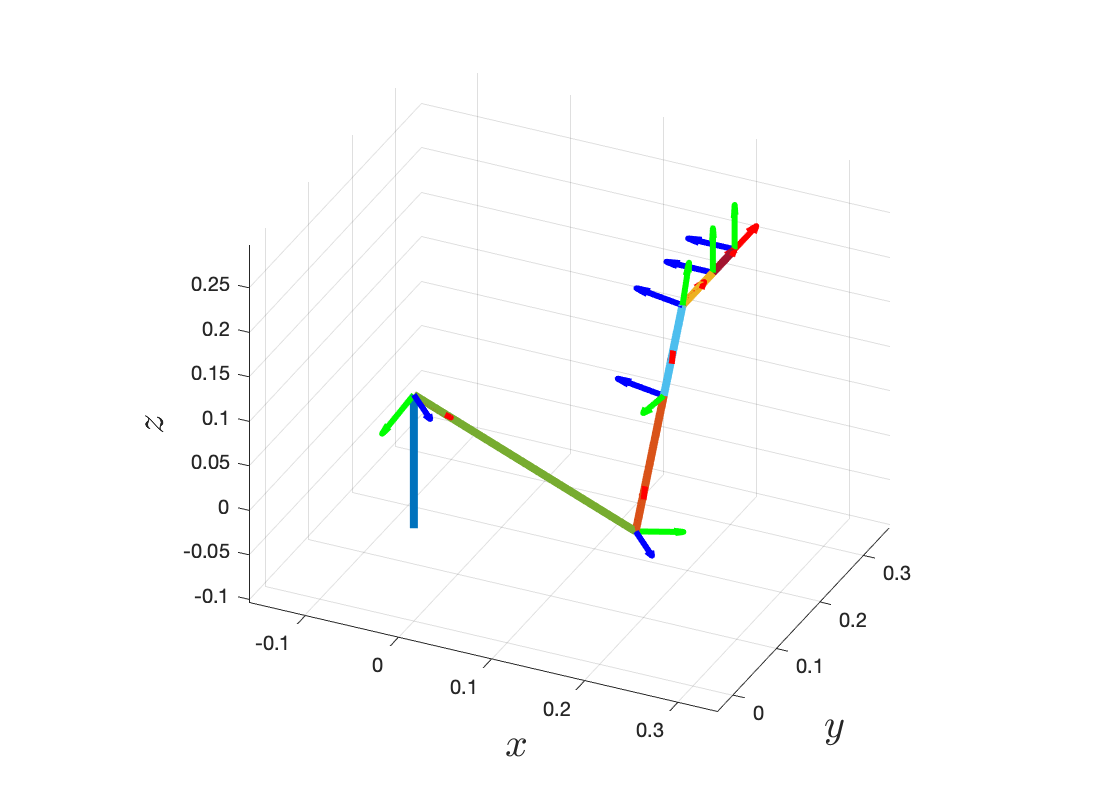


% draw figure
drawLine3D(o1,o2);
drawCoordinate3DScale(R2,o2, 0.05);
drawLine3D(o2,o3);
drawCoordinate3DScale(R3,o3, 0.05);
drawLine3D(o3,o4);
drawCoordinate3DScale(R4,o4, 0.05);
drawLine3D(o4,o5);
drawCoordinate3DScale(R5,o5, 0.05);
drawLine3D(o5,o6);
drawCoordinate3DScale(R6,o6, 0.05);
drawLine3D(o6,oee);
drawCoordinate3DScale(Ree,oee, 0.05);
% R = eye(3);
xlabel('$x$','interpreter','latex','fontsize',20)
ylabel('$y$','interpreter','latex','fontsize',20)
zlabel('$z$','interpreter','latex','fontsize',20)
axis equal
fig=gcf;
fig.Position(3:4)=[550,400];


view(25,30)

function [J,Tcur] = Jacobian(th)
    th1 = th(1);
    th2 = th(2);
    th3 = th(3);
    th4 = th(4);
    th5 = th(5);
    th6 = th(6);
    syms theta
    Rx = [1, 0, 0;
        0, cos(theta), -sin(theta);
        0 sin(theta), cos(theta);
        ];
    Ry = [cos(theta), 0, sin(theta);
        0, 1, 0;
        -sin(theta), 0, cos(theta);
        ];
    Rz = [cos(theta), -sin(theta), 0;
        sin(theta), cos(theta), 0;
        0 0, 1;
        ];
    syms p1 p2 p3
    P = [p1;  p2; p3];
    Tx =[Rx, P;
        0 0 0 1];
    Ty =[Ry, P;
        0 0 0 1];
    Tz =[Rz, P;
        0 0 0 1];
    T01 = subs(Tz,{theta,p1, p2, p3},{th1,0,0,0});
    T12 = subs(Ty,{theta,p1, p2, p3},{th2,0,0,0.15});
    T23 = subs(Ty,{theta,p1, p2, p3},{th3,0.3,0,0});
    T34 = subs(Tx,{theta,p1, p2, p3},{th4,0.15,0,0});
    T45 = subs(Ty,{theta,p1, p2, p3},{th5,0.1,0,0});
    T56 = subs(Tx,{theta,p1, p2, p3},{th6,0.07,0,0});
    T6EE = subs(Tx,{theta,p1, p2, p3},{0,0.05,0,0});
    
    T5EE = Tmul(T56, T6EE);
    T4EE = Tmul(T45, T5EE);
    T3EE = Tmul(T34, T4EE);
    T2EE = Tmul(T23, T3EE);
    T1EE = Tmul(T12, T2EE);
    T0EE = Tmul(T01, T1EE);
    
    TEE0 = Tinv(T0EE);
    TEE1 = Tinv(T1EE);
    TEE2 = Tinv(T2EE);
    TEE3 = Tinv(T3EE);
    TEE4 = Tinv(T4EE);
    TEE5 = Tinv(T5EE);
    TEE6 = Tinv(T6EE);
    
    Adj_EE1 = Adj(TEE1);
    Adj_EE2 = Adj(TEE2);
    Adj_EE3 = Adj(TEE3);
    Adj_EE4 = Adj(TEE4);
    Adj_EE5 = Adj(TEE5);
    Adj_EE6 = Adj(TEE6);
    
    s1 = [0;0;1;0;0;0];
    s2 = [0;1;0;0;0;0];
    s3 = [0;1;0;0;0;0];
    s4 = [1;0;0;0;0;0];
    s5 = [0;1;0;0;0;0];
    s6 = [1;0;0;0;0;0];
    eeJee = [Adj_EE1*s1, Adj_EE2*s2,Adj_EE3*s3,Adj_EE4*s4,Adj_EE5*s5,Adj_EE6*s6];
    
    R0EE = T0EE(1:3,1:3);
    J = double([R0EE, zeros(3); zeros(3), R0EE]*eeJee);
    Tcur = double(T0EE);
end
function [o1,R1, o2,R2, o3,R3, o4,R4, o5,R5, o6, R6, oee, Ree] = arm(th)
    th1 = th(1);
    th2 = th(2);
    th3 = th(3);
    th4 = th(4);
    th5 = th(5);
    th6 = th(6);
    syms theta
    Rx = [1, 0, 0;
        0, cos(theta), -sin(theta);
        0 sin(theta), cos(theta);
        ];
    Ry = [cos(theta), 0, sin(theta);
        0, 1, 0;
        -sin(theta), 0, cos(theta);
        ];
    Rz = [cos(theta), -sin(theta), 0;
        sin(theta), cos(theta), 0;
        0 0, 1;
        ];
    syms p1 p2 p3
    P = [p1;  p2; p3];
    Tx =[Rx, P;
        0 0 0 1];
    Ty =[Ry, P;
        0 0 0 1];
    Tz =[Rz, P;
        0 0 0 1];
    T01 = subs(Tz,{theta,p1, p2, p3},{th1,0,0,0});
    T12 = subs(Ty,{theta,p1, p2, p3},{th2,0,0,0.15});
    T23 = subs(Ty,{theta,p1, p2, p3},{th3,0.3,0,0});
    T34 = subs(Tx,{theta,p1, p2, p3},{th4,0.15,0,0});
    T45 = subs(Ty,{theta,p1, p2, p3},{th5,0.1,0,0});
    T56 = subs(Tx,{theta,p1, p2, p3},{th6,0.07,0,0});
    T6EE = subs(Tx,{theta,p1, p2, p3},{0,0.05,0,0});
    
    [R1, o1] = Textract(T01);
    
    T02 = Tmul(T01, T12);
    [R2, o2] = Textract(T02);
    
    T03 = Tmul(T02, T23);
    [R3, o3] = Textract(T03);
    
    T04 = Tmul(T03, T34);
    [R4, o4] = Textract(T04);
    
    T05 = Tmul(T04, T45);
    [R5, o5] = Textract(T05);
    
    T06 = Tmul(T05, T56);
    [R6, o6] = Textract(T06);
    
    T0EE = Tmul(T06, T6EE);
    oee = T0EE(1:3,4);    
    Ree = T0EE(1:3,1:3);
end

function Tres = Tmul(T1, T2)
    Tres = T1 * T2;
end

function Tres = Tinv(T)
    R = T(1:3,1:3);
    p = T(1:3,4);
    
    Tres =[R.', -R.' * p;
    0 0 0 1];
end

function [R,p] = Textract(T)
    R = T(1:3,1:3);
    p = T(1:3,4);
end
function AdjT = Adj(T)
    AdjT = zeros(4);
    P = [T(1,4), T(2,4), T(3,4)];
    PSkew = [0 -P(3) P(2); 
             P(3) 0 -P(1); 
             -P(2) P(1) 0];
    AdjT(1:3,1:3) = T(1:3,1:3); 
    AdjT(4:6,4:6) = T(1:3,1:3); 
    AdjT(4:6,1:3) = Tmul(PSkew, T(1:3,1:3));   
end

function error = Efunc(Tdes,Tcur)
    wmatr = logm(Tdes(1:3,1:3) * Tcur(1:3,1:3)');
    error = [wmatr(3,2); wmatr(1,3); wmatr(2,1); Tdes(1:3,4)-Tcur(1:3,4)];
    error = double(error);
end